# LDA Demo 

Assumption

- Normally distributed

- Equal class covariances:  COV(X,X)==COV(Y,Y)

## Example 1: 2-class classification

- Dimension(feature number) p=2

- Class num K=2

- Total dataset N=6

#### Create Dataset

N1=3; N2=3; N=N1+N2; K=2;
% Dataset
x1=[1;3]; x2=[2;3]; x3=[2;4]; x4=[3;1]; x5=[3;2]; x6=[4;2];
% Label  class 1
y1 = 1; y2 = 1; y3 = 1;
% Label class 2
y4 = 2; y5 = 2; y6 = 2;

X=[x1 x2 x3 x4 x5 x6]

X =      1     2     2     3     3     4
     3     3     4     1     2     2


Y=[y1 y2 y3 y4 y5 y6]

Y =      1     1     1     2     2     2


#### Estimate Linear Discriminant functions

% Prior
pi1=N1/N

pi1 = 0.5000

pi2=N2/N

pi2 = 0.5000

% mu
mu1=sum(X(:,1:3),2)/ N1

mu1 =     1.6667
    3.3333


mu2=sum(X(:,4:6),2)/ N2

mu2 =     3.3333
    1.6667


### Covariance Matrix 

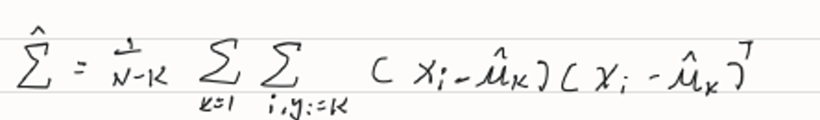

%covariance
sum_temp1=0;

for i=1:N1
  	sum_temp1=sum_temp1+(X(:,i)-mu1)*(X(:,i)-mu1)';
end

sum_temp2=sum_temp1;

for i=N1+1:N
	sum_temp2=sum_temp2+(X(:,i)-mu2)*(X(:,i)-mu2)';
end

%cov(X,X)=cov(Y,Y)
cov=1/(N-K)*sum_temp2

cov =     0.3333    0.1667
    0.1667    0.3333


icov = inv(cov)

icov =     4.0000   -2.0000
   -2.0000    4.0000


% Delta
LD1=@(x) x'*(icov)*(mu1)-0.5*(mu1)'*(icov)*(mu1)+log(pi1);
LD2=@(x) x'*(icov)*(mu2)-0.5*(mu2)'*(icov)*(mu2)+log(pi2);

% LD1  = w11*x+w10
w11=(icov)*(mu1)

w11 =     0.0000
   10.0000


w10=-0.5*(mu1)'*(icov)*(mu1)+log(pi1)

w10 = -17.3598

% LD2  = w21*x+w20
w21=(icov)*(mu2)

w21 =    10.0000
         0


w20=-0.5*(mu2)'*(icov)*(mu2)+log(pi2)

w20 = -17.3598